# ------------------ UVSPEC WRAPPER -----------------

% -----------------------------------------------------------


% This script will write .INP files using writeUVSPEC.m, run the created
% files using runUVSPEC/m, and then read the .OUT files using readUVSPEC.m.
% The intention of the script is to control the radiative transfer code
% UVSPEC from Matlab. The user will be able to create files, run them and
% view the results here in this live script


clear variables;

addLibRadTran_paths

% Created by Andrew J. Buggee

## DESIGNATE INPUT AND OUTPUT FILES AND FLAGS

% for now, we will manually create uvspec.inp files, and simply call them
% out as variables
which_computer = whatComputer;


% inputName = 'UVSPEC_MC.INP';
inputName = 'example_highRes_spectrum_forDefense.INP';

outputName = inputName(1:end-4);



% ----- We need folder locations so we know where the file are -----

if strcmp(which_computer, 'andrewbuggee')==true

    % ---------------------------------------------
    % ------------------- MACBOOK -----------------
    % ---------------------------------------------

%     folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/Hyperspectral-Cloud-Droplet-Retrieval/',...
%         'LibRadTran/libRadtran-2.0.4/MODIS_day_194_year_2021_time_1935/'];


    % libRadtran folder for testing UVSPEV files
    % folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/Hyperspectral-Cloud-Droplet-Retrieval/',...
    %     'LibRadTran/libRadtran-2.0.4/testing_UVSPEC/'];

    % libRadtran folder for testing UVSPEV files
    folderName = ['/Users/andrewbuggee/Documents/libRadtran-2.0.6/example_spectra/'];


    % libRadtran examples folder
    % folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/',...
    %     'Hyperspectral-Cloud-Droplet-Retrieval/LibRadTran/libRadtran-2.0.4/examples/'];



elseif strcmp(which_computer, 'anbu8374')==true

    % ---------------------------------------------
    % ----------------- MAC DESKTOP ---------------
    % ---------------------------------------------

    % folderName = ['/Users/anbu8374/Documents/LibRadTran/libRadtran-2.0.4/MODIS_day_314_year_2008_time_1440/'];
    %
    folderName = '/Users/anbu8374/Documents/LibRadTran/libRadtran-2.0.4/testing_UVSPEC/';
    %


end





% ----- FLAGS!!! -----

readOnly = false; % if true, the output has already been produced, and we want to read in results without running uvspec again




## RUN UVSPEC AND SAVE INPUTS/OUTPUTS



if readOnly == true
    % do nothing

elseif readOnly == false

    tic
    runUVSPEC_ver2(folderName,inputName,outputName, which_computer);
    toc


end

Elapsed time is 337.927871 seconds.


## READ UVSPEC OUTPUT FILES

% Define the inputs
inputs.RT.rte_solver = 'disort';
inputs.RT.vza = acosd(0.997200);     % This is how it's coded in the function 'write-INP-file
inputs.RT.vaz = 257.210000;
compute_reflectivity = false;

% read .OUT file
% radiance is in units of mW/nm/m^2/sr
[ds,~,~] = readUVSPEC_ver2(folderName, outputName, inputs,...
    compute_reflectivity);



## PLOT AND ANALYZE OUTPUT FILES

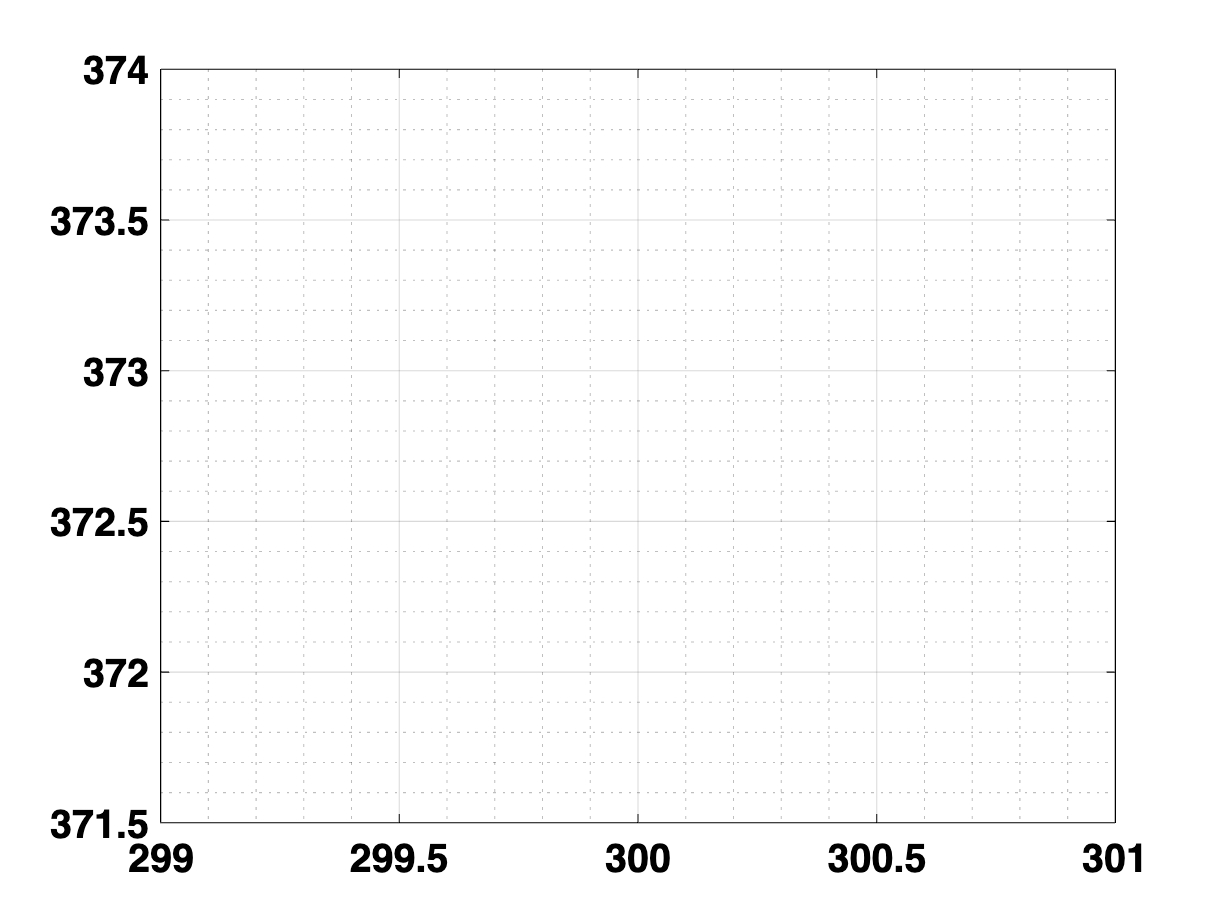

Undefined variable 'irrad_HU'.


% Next lets plot the radiance data

% lets check and see how many geometry settings there are

geomSets = length(inputSettings{2,2})*length(inputSettings{2,3});

if geomSets <= 3

    if iscell(ds)==false

        figure;
        legendString = cell(1,geomSets);
        for ii = 1:geomSets
            plot(ds.wavelength,ds.radiance(ii).rad_umu_phi,'LineWidth',1)
            hold on
            legendString{ii} = ds.radiance(ii).umu_phi;
        end

        grid on; grid minor
        title(rad_HU{1,2})
        xlabel(irrad_HU{2,1})
        ylabel(rad_HU{2,2})
        legend(legendString)

    else

        figure;

        changingVariable = [20,25,30]; % we assume if ds is a cell, you are changing a variable that must be changed from file to file. Enter the changing variable here
        legendString = cell(1,length(ds));
        for ii = 1:length(index2Plot)
            plot(ds{ii}.wavelength,ds{ii}.radiance.rad_umu_phi,'LineWidth',1)
            hold on
            legendString{ii} = num2str(changingVariable(ii));
        end

        grid on; grid minor
        title(rad_HU{1,2})
        xlabel(irrad_HU{2,1})
        ylabel(rad_HU{2,2})
        legend(legendString)
    end

    % more than 3 geometries, plot as many as you'd like!
elseif geomSets > 3

    if iscell(ds)==true % haven't made this work yet
        error('Havent made this code work yet!')
    end

    index2plot = [1,round(geomSets/2),geomSets];
    index2plot = [1,2,3,4,5,6];

    figure;
    sp1 = subplot(1,2,1);
    legendString = cell(1,length(index2plot));
    for ii = 1:length(index2plot)
        plot(ds.wavelength,ds.radiance(index2plot(ii)).rad_umu_phi,'LineWidth',1)
        hold on
        legendString{ii} = ds.radiance(index2plot(ii)).umu_phi;
    end

    sp1.Parent.Position(3) = sp1.Parent.Position(3)+300; % this will make the subplots wider by 300 pixels
    grid on; grid minor
    title(rad_HU{1,2})
    xlabel(irrad_HU{2,1})
    ylabel(rad_HU{2,2})
    legend(legendString)

    r = 1;
    sp2 = subplot(1,2,2);
    % Plot the position of the sun
    polarplot(pi/180*inputSettings{2,5},r*sind(inputSettings{2,4}),'*','MarkerSize',15,'Color',[0.9290, 0.6940, 0.1250])
    hold on
    set(gca,'ColorOrderIndex',1)
    for ii = 1:length(index2plot)
        geom = str2num(ds.radiance(index2plot(ii)).umu_phi); %#ok<ST2NM> % first value is umu, second is azimuth
        sinT = sqrt(1 - geom(1).^2);

        polarplot(pi/180*geom(2),r*sinT,'.','MarkerSize',12)
        hold on
    end
    set(gca,'FontSize',14)
    title('Geometry of Sun and Looks','FontSize',20)

else

    index2plot = [1,round(geomSets/2),geomSets];


    figure;
    sp1 = subplot(1,2,1);
    legendString = cell(1,length(index2plot));
    for ii = 1:length(index2plot)
        plot(ds.wavelength,ds.radiance(index2plot(ii)).rad_umu_phi,'LineWidth',1)
        hold on
        legendString{ii} = ds.radiance(index2plot(ii)+1).umu_phi;
    end

    sp1.Parent.Position(3) = sp1.Parent.Position(3)+300; % this will make the subplots wider by 300 pixels
    grid on; grid minor
    title(rad_HU{1,2})
    xlabel(irrad_HU{2,1})
    ylabel(rad_HU{2,2})
    legend(legendString,'TextColor','w','Location',"best")

    r = 1;
    sp2 = subplot(1,2,2);
    % Plot the position of the sun
    polarplot(pi/180*inputSettings{2,5},r*sind(inputSettings{2,4}),'*','MarkerSize',15,'Color',[0.9290, 0.6940, 0.1250])
    hold on
    set(gca,'ColorOrderIndex',1)
    for ii = 1:length(index2plot)
        geom = str2num(ds.radiance(index2plot(ii)).umu_phi); %#ok<ST2NM> % first value is umu, second is azimuth
        sinT = sqrt(1 - geom(1).^2);

        polarplot(pi/180*geom(2),r*sinT,'.','MarkerSize',12)
        hold on
    end
    set(gca,'FontSize',14)
    title('Geometry of Sun and Looks','FontSize',20)



end

